m = 1.0;
cp_nom = 1.0;
cv_nom = 1.0;

Delta_cp = 0.1;
Delta_cv = 0.075;

cp = ureal('cp', cp_nom, 'Range', [cp_nom - Delta_cp, cp_nom + Delta_cp]);
cv = ureal('cv', cv_nom, 'Range', [cv_nom - Delta_cv, cv_nom + Delta_cv]);

A_nom = [0, 1; -cp_nom/m, -cv_nom/m];
B_nom = [0; cp_nom/m];
C_nom = [1, 0];
D_nom = 0;

G_nom = ss(A_nom, B_nom, C_nom, D_nom);

A_unc = [0, 1; -cp/m, -cv/m];
B_unc = [0; cp/m];

G_unc = uss(A_unc, B_unc, C_nom, D_nom);

W1 = makeweight(100, 6*pi, 0.9);   % error
W2 = ss(0);  % control input
W3 = makeweight(1.1, 500*pi, 0.01);  % output

[K, CL, gamma] = mixsyn(G_unc, W1, W2, W3);

gapmetric(G_unc, K)

ans = 1

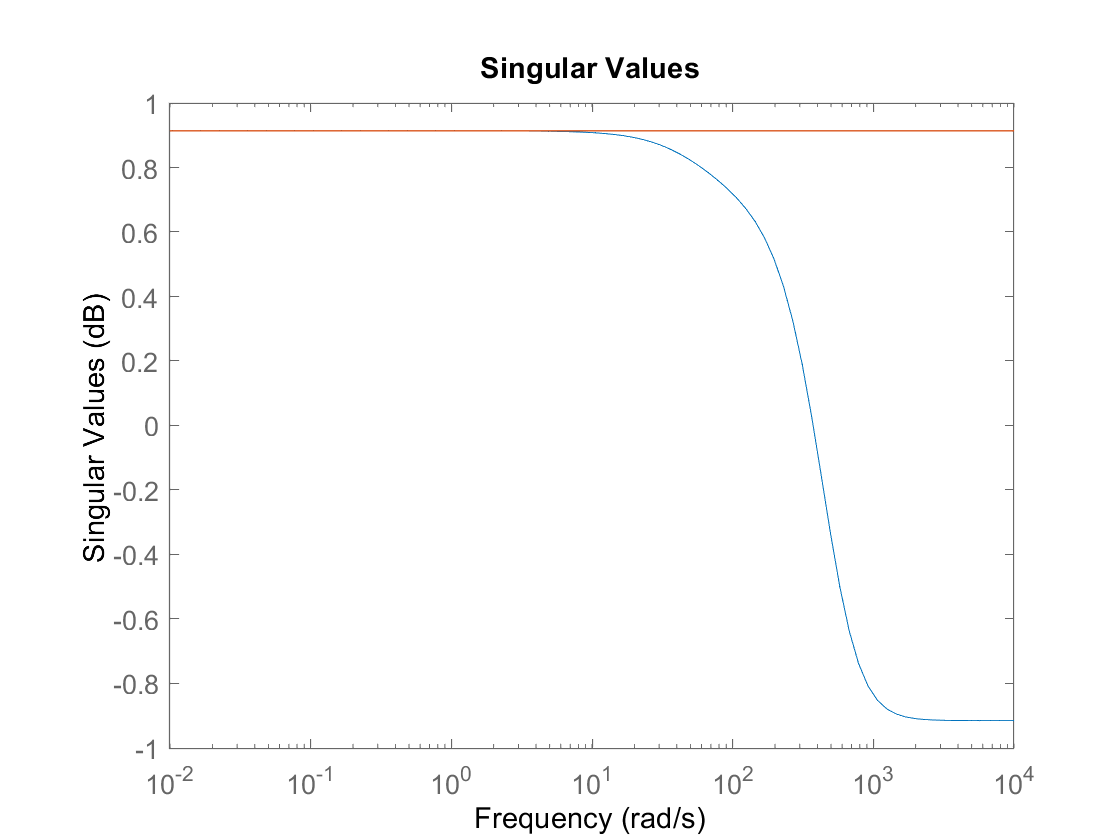


sigma(CL,ss(gamma))